# Custom HBC Channel Models

### CM1

% CM1
CM1data = table2array(readtable("CM1_ChannelResponse.csv","NumHeaderLines",4)); % Obtaining data from COMSOL

freq = [0 ; abs(CM1data(:,1))]; % Creating the frequency vector for graph plotting
norm_freq = freq/(80E6); 
complex_CM1 = [0 ; CM1data(:,2)]; 
% mag_CM1 = 20*log10(abs(complex_CM1)); %Computing magnitude response
% ang_CM1 = angle(complex_CM1);  % Computing phase response
CM1 = fdesign.arbmagnphase('N,F,H', 50, norm_freq', complex_CM1'); 

%CM1_filter = design(CM1, 'allfir', SystemObject = true); %Design filter using all valid methods
% 
% % Plotting Magnitude Response
% figure
% [H1, W] = freqz(CM1_filter{1});
% H2 = freqz(CM1_filter{2});
% H3 = freqz(CM1_filter{3});
% plot((W/pi)*(80E6),db(H1))
% hold on
% plot((W/pi)*(80E6),db(H2))
% plot((W/pi)*(80E6),db(H3))
% plot(freq,db(complex_CM1),'k--')
% hold off
% title('Magnitude Response against Frequency')
% ylabel('Magnitude/ dB')
% xlabel('Frequency/ Hz')
% legend('Equiripple Hd(1)', 'FIR Least-Squares Hd(2)','Frequency Sampling  Hd(3)','Nominal Response',Location = 'SouthEast')
% 
% % Plotting Phase Response
% figure
% [H1, W] = freqz(CM1_filter{1});
% H2 = freqz(CM1_filter{2});
% H3 = freqz(CM1_filter{3});
% plot((W/pi)*(80E6),angle(H1))
% hold on
% plot((W/pi)*(80E6),-angle(H2))
% plot((W/pi)*(80E6),-angle(H3))
% plot(freq,angle(complex_CM1),'k--')
% hold off
% title('Phase Response against Frequency')
% ylabel('Magnitude/ dB')
% xlabel('Frequency/ Hz')
% legend('Equiripple Hd(1)', 'FIR Least-Squares Hd(2)','Frequency Sampling  Hd(3)','Nominal Response',Location = 'NorthEast')

% % Error Analysis: 
% 
% % Upsample the complex CM1 values to match the length of the filter values
% CM1_interp = interp1(freq, complex_CM1,(W/pi)*(80E6)); 
% freq_non_norm = (W/pi)*(80E6); 
% HBCindx = find((freq_non_norm >= 18.375E6)&(freq_non_norm <= 23.625E6));
% 
% % Magnitude
% abs_error_mag1 = mean(abs(db(CM1_interp(2:length(H1))) - db(H1(2:length(H1))))) % Equiripple Method
% abs_error_mag2 = mean(abs(db(CM1_interp(2:length(H1))) - db(H2(2:length(H1)))))% Least Square FIR
% abs_error_mag3 = mean(abs(db(CM1_interp(2:length(H1))) - db(H3(2:length(H1))))) % Frequency Sampling
% 
% % Phase
% abs_error_ph1 = mean(abs(angle(CM1_interp(2:length(H1))) - angle(H1(2:length(H1))))) % Equiripple Method
% abs_error_ph2 = mean(abs(angle(CM1_interp(2:length(H1))) - -angle(H2(2:length(H1)))))% Least Square FIR
% abs_error_ph3 = mean(abs(angle(CM1_interp(2:length(H1))) - -angle(H3(2:length(H1))))) % Frequency Sampling
% 
% % HBC Band: 
% % Magnitude
% abs_error_HBCmag1 = mean(abs(db(CM1_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H1(HBCindx(1):HBCindx(length(HBCindx)))))) % Equiripple Method
% abs_error_HBCmag2 = mean(abs(db(CM1_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H2(HBCindx(1):HBCindx(length(HBCindx)))))) % Least Square FIR
% abs_error_HBCmag3 = mean(abs(db(CM1_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H3(HBCindx(1):HBCindx(length(HBCindx)))))) % Frequency Sampling
% 
% % Phase
% abs_error_HBCph1 = mean(abs(angle(CM1_interp(HBCindx(1):HBCindx(length(HBCindx)))) - angle(H1(HBCindx(1):HBCindx(length(HBCindx)))))) % Equiripple Method
% abs_error_HBCph2 = mean(abs(angle(CM1_interp(HBCindx(1):HBCindx(length(HBCindx)))) - -angle(H2(HBCindx(1):HBCindx(length(HBCindx)))))) % Least Square FIR
% abs_error_HBCph3 = mean(abs(angle(CM1_interp(HBCindx(1):HBCindx(length(HBCindx)))) - -angle(H3(HBCindx(1):HBCindx(length(HBCindx)))))) % Frequency Sampling


% Design using the frequency sampling method. 
CM1_filter = design(CM1, 'freqsamp', SystemObject = true); %Design filter using frequency sampling method

% % Plotting Magnitude Response vs Normalized Frequency
% figure
% [H, W] = freqz(CM1_filter); 
% plot((W/pi)*(80E6), db(H))
% hold on
% plot((norm_freq)*(80E6),db(complex_CM1),'k--')
% legend('Abstracted CM1 Filter', 'Actual CM1 Response',Location = 'southeast')
% title('Magnitude Response against Frequency')
% ylabel('Magnitude/ dB')
% xlabel('Frequency/ Hz')
% 
% % Plotting Phase Response vs Normalized Frequency
% figure
% plot((W/pi)*(80E6), (angle(H))*(-180/pi))
% hold on
% plot((norm_freq)*(80E6),(angle(complex_CM1))*(180/pi),'k--')
% legend('Abstracted CM1 Filter', 'Actual CM1 Response',Location = 'southeast')
% title('Voltage Gain and Phase Response against Frequency')
% ylabel('Phase/ degrees')
% xlabel('Frequency/ Hz')


### CM2

% CM2
CM2data = table2array(readtable("CM2_ChannelResponse.csv","NumHeaderLines",4)); % Obtaining data from COMSOL

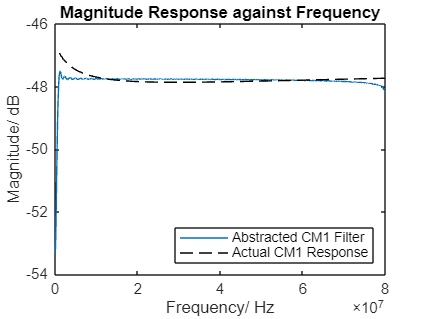

freq = [0 ; abs(CM2data(:,1))]; % Creating the frequency vector for graph plotting
norm_freq = freq/(80E6); 
complex_CM2 = [0 ; CM2data(:,2)]; 
% mag_CM1 = 20*log10(abs(complex_CM2)); %Computing magnitude response
% ang_CM1 = angle(complex_CM2);  % Computing phase response
CM2 = fdesign.arbmagnphase('N,F,H', 125, norm_freq', complex_CM2'); 

%CM2_filter = design(CM2, 'allfir', SystemObject = true); %Design filter using all valid methods

% % Plotting Magnitude Response
% figure
% [H1, W] = freqz(CM2_filter{1});
% H2 = freqz(CM2_filter{2});
% H3 = freqz(CM2_filter{3});
% plot((W/pi)*(80E6),db(H1))
% hold on
% plot((W/pi)*(80E6),db(H2))
% plot((W/pi)*(80E6),db(H3))
% plot(freq,db(complex_CM2),'k--')
% hold off
% title('Magnitude Response against Frequency')
% ylabel('Magnitude/ dB')
% xlabel('Frequency/ Hz')
% legend('Equiripple Hd(1)', 'FIR Least-Squares Hd(2)','Frequency Sampling  Hd(3)','Nominal Response',Location = 'SouthEast')
% 
% % Plotting Phase Response
% figure
% [H1, W] = freqz(CM2_filter{1});
% H2 = freqz(CM2_filter{2});
% H3 = freqz(CM2_filter{3});
% plot((W/pi)*(80E6),angle(H1))
% hold on
% plot((W/pi)*(80E6),-angle(H2))
% plot((W/pi)*(80E6),-angle(H3))
% plot(freq,angle(complex_CM2),'k--')
% hold off
% title('Phase Response against Frequency')
% ylabel('Phase/ rad')
% xlabel('Frequency/ Hz')
% legend('Equiripple Hd(1)', 'FIR Least-Squares Hd(2)','Frequency Sampling  Hd(3)','Nominal Response',Location = 'NorthEast')

% % Error Analysis: 
% 
% % Upsample the complex CM1 values to match the length of the filter values
% CM2_interp = interp1(freq, complex_CM2,(W/pi)*(80E6)); 
% freq_non_norm = (W/pi)*(80E6); 
% HBCindx = find((freq_non_norm >= 18.375E6)&(freq_non_norm <= 23.625E6));
% 
% % Magnitude
% abs_error_mag1 = mean(abs(db(CM2_interp(2:length(H1))) - db(H1(2:length(H1))))) % Equiripple Method
% abs_error_mag2 = mean(abs(db(CM2_interp(2:length(H1))) - db(H2(2:length(H1)))))% Least Square FIR
% abs_error_mag3 = mean(abs(db(CM2_interp(2:length(H1))) - db(H3(2:length(H1))))) % Frequency Sampling
% 
% % Phase
% abs_error_ph1 = mean(abs(angle(CM2_interp(2:length(H1))) - angle(H1(2:length(H1))))) % Equiripple Method
% abs_error_ph2 = mean(abs(angle(CM2_interp(2:length(H1))) - -angle(H2(2:length(H1)))))% Least Square FIR
% abs_error_ph3 = mean(abs(angle(CM2_interp(2:length(H1))) - -angle(H3(2:length(H1))))) % Frequency Sampling
% 
% % HBC Band: 
% % Magnitude
% abs_error_HBCmag1 = mean(abs(db(CM2_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H1(HBCindx(1):HBCindx(length(HBCindx)))))) % Equiripple Method
% abs_error_HBCmag2 = mean(abs(db(CM2_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H2(HBCindx(1):HBCindx(length(HBCindx)))))) % Least Square FIR
% abs_error_HBCmag3 = mean(abs(db(CM2_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H3(HBCindx(1):HBCindx(length(HBCindx)))))) % Frequency Sampling
% 
% % Phase
% abs_error_HBCph1 = mean(abs(angle(CM2_interp(HBCindx(1):HBCindx(length(HBCindx)))) - angle(H1(HBCindx(1):HBCindx(length(HBCindx)))))) % Equiripple Method
% abs_error_HBCph2 = mean(abs(angle(CM2_interp(HBCindx(1):HBCindx(length(HBCindx)))) - -angle(H2(HBCindx(1):HBCindx(length(HBCindx)))))) % Least Square FIR
% abs_error_HBCph3 = mean(abs(angle(CM2_interp(HBCindx(1):HBCindx(length(HBCindx)))) - -angle(H3(HBCindx(1):HBCindx(length(HBCindx)))))) % Frequency Sampling


% Design using the frequency sampling method. 
CM2_filter = design(CM2, 'firls', SystemObject = true); %Design filter using frequency sampling method

% Plotting Magnitude Response vs Normalized Frequency
figure
[H, W] = freqz(CM2_filter); 
plot((W/pi)*(80E6), db(H))
hold on
plot((norm_freq)*(80E6),db(complex_CM2),'k--')
legend('Abstracted CM1 Filter', 'Actual CM1 Response',Location = 'southeast')
title('Magnitude Response against Frequency')
ylabel('Magnitude/ dB')
xlabel('Frequency/ Hz')

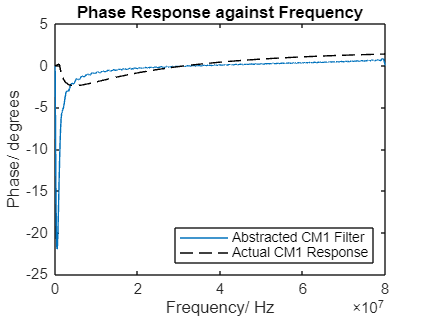


% Plotting Phase Response vs Normalized Frequency
figure
plot((W/pi)*(80E6), (angle(H))*(-180/pi))
hold on
plot((norm_freq)*(80E6),(angle(complex_CM2))*(180/pi),'k--')
legend('Abstracted CM1 Filter', 'Actual CM1 Response',Location = 'southeast')
title('Phase Response against Frequency')
ylabel('Phase/ degrees')
xlabel('Frequency/ Hz')

### CM3

CM3data = table2array(readtable("CM3_ChannelResponse.csv","NumHeaderLines",4)); % Obtaining data from COMSOL

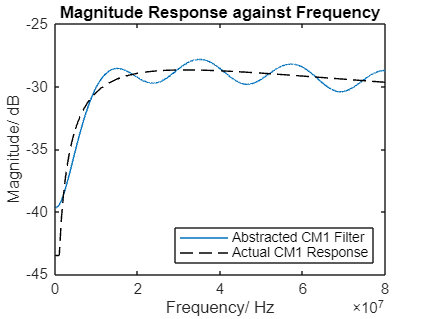

freq = [0 ; abs(CM3data(:,1))]; % Creating the frequency vector for graph plotting
norm_freq = freq/(80E6); 
complex_CM3 = [CM3data(1,2) ; CM3data(:,2)]; 
% mag_CM1 = 20*log10(abs(complex_CM2)); %Computing magnitude response
% ang_CM1 = angle(complex_CM2);  % Computing phase response

%CM3 = fdesign.arbmagnphase('N,F,H', 50, norm_freq', complex_CM3'); 
CM3 = fdesign.arbmag('N,F,A', 14, norm_freq', abs(complex_CM3)');

% CM3_filter = design(CM3, 'allfir', SystemObject = true); %Design filter using all valid methods
% 
% % Plotting Magnitude Response
% figure
% [H1, W] = freqz(CM3_filter{1});
% H2 = freqz(CM3_filter{2});
% H3 = freqz(CM3_filter{3});
% f = (W*80E6)/(pi); 
% plot(f,db(H1))
% hold on
% plot(f,db(H2))
% plot(f,db(H3))
% plot(freq,db(complex_CM3),'k--')
% hold off
% title('Magnitude Response against Frequency')
% ylabel('Magnitude/ dB')
% xlabel('Frequency/ Hz')
% legend('Equiripple Hd(1)', 'FIR Least-Squares Hd(2)','Frequency Sampling  Hd(3)','Nominal Response',Location = 'SouthEast')
% 
% % Plotting Phase Response
% figure
% [H1, W] = freqz(CM3_filter{1});
% H2 = freqz(CM3_filter{2});
% H3 = freqz(CM3_filter{3});
% plot((W/pi)*(80E6),angle(H1))
% hold on
% plot((W/pi)*(80E6),-angle(H2))
% plot((W/pi)*(80E6),-angle(H3))
% plot(freq,angle(complex_CM3),'k--')
% hold off
% title('Phase Response against Frequency')
% ylabel('Phase/ rad')
% xlabel('Frequency/ Hz')
% legend('Equiripple Hd(1)', 'FIR Least-Squares Hd(2)','Frequency Sampling  Hd(3)','Nominal Response',Location = 'NorthEast')
% 
% % Error Analysis: 
% 
% % Upsample the complex CM1 values to match the length of the filter values
% CM3_interp = interp1(freq, complex_CM3,(W/pi)*(80E6)); 
% freq_non_norm = (W/pi)*(80E6); 
% HBCindx = find((freq_non_norm >= 18.375E6)&(freq_non_norm <= 23.625E6));
% 
% % Magnitude
% abs_error_mag1 = mean(abs(db(CM3_interp(2:length(H1))) - db(H1(2:length(H1))))) % Equiripple Method
% abs_error_mag2 = mean(abs(db(CM3_interp(2:length(H1))) - db(H2(2:length(H1)))))% Least Square FIR
% abs_error_mag3 = mean(abs(db(CM3_interp(2:length(H1))) - db(H3(2:length(H1))))) % Frequency Sampling
% 
% % Phase
% abs_error_ph1 = mean(abs(angle(CM3_interp(2:length(H1))) - angle(H1(2:length(H1))))) % Equiripple Method
% abs_error_ph2 = mean(abs(angle(CM3_interp(2:length(H1))) - -angle(H2(2:length(H1)))))% Least Square FIR
% abs_error_ph3 = mean(abs(angle(CM3_interp(2:length(H1))) - -angle(H3(2:length(H1))))) % Frequency Sampling
% 
% % HBC Band: 
% % Magnitude
% abs_error_HBCmag1 = mean(abs(db(CM3_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H1(HBCindx(1):HBCindx(length(HBCindx)))))) % Equiripple Method
% abs_error_HBCmag2 = mean(abs(db(CM3_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H2(HBCindx(1):HBCindx(length(HBCindx)))))) % Least Square FIR
% abs_error_HBCmag3 = mean(abs(db(CM3_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H3(HBCindx(1):HBCindx(length(HBCindx)))))) % Frequency Sampling
% 
% % Phase
% abs_error_HBCph1 = mean(abs(angle(CM3_interp(HBCindx(1):HBCindx(length(HBCindx)))) - angle(H1(HBCindx(1):HBCindx(length(HBCindx)))))) % Equiripple Method
% abs_error_HBCph2 = mean(abs(angle(CM3_interp(HBCindx(1):HBCindx(length(HBCindx)))) - -angle(H2(HBCindx(1):HBCindx(length(HBCindx)))))) % Least Square FIR
% abs_error_HBCph3 = mean(abs(angle(CM3_interp(HBCindx(1):HBCindx(length(HBCindx)))) - -angle(H3(HBCindx(1):HBCindx(length(HBCindx)))))) % Frequency Sampling


% Design using the frequency sampling method. 
CM3_filter = design(CM3, 'equiripple', SystemObject = true); %Design filter using frequency sampling method

% Plotting Magnitude Response vs Normalized Frequency
figure
[H, W] = freqz(CM3_filter); 
plot((W/pi)*(80E6), db(H))
hold on
plot((norm_freq)*(80E6),db(complex_CM3),'k--')
legend('Abstracted CM1 Filter', 'Actual CM1 Response',Location = 'southeast')
title('Magnitude Response against Frequency')
ylabel('Magnitude/ dB')
xlabel('Frequency/ Hz')

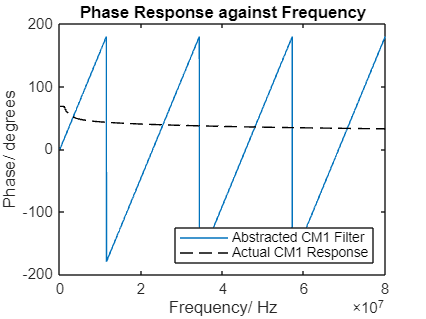


% Plotting Phase Response vs Normalized Frequency
figure
plot((W/pi)*(80E6), (angle(H))*(-180/pi))
hold on
plot((norm_freq)*(80E6),(angle(complex_CM3))*(180/pi),'k--')
legend('Abstracted CM1 Filter', 'Actual CM1 Response',Location = 'southeast')
title('Phase Response against Frequency')
ylabel('Phase/ degrees')
xlabel('Frequency/ Hz')

### CM4

CM4data = table2array(readtable("CM4_ChannelResponse.csv","NumHeaderLines",4)); % Obtaining data from COMSOL

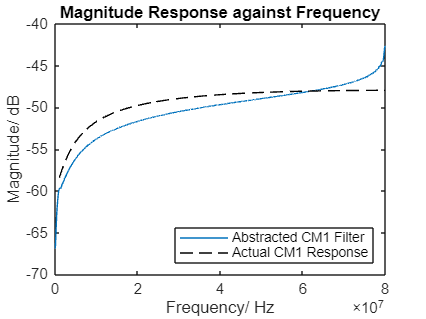

freq = [0 ; abs(CM4data(:,1))]; % Creating the frequency vector for graph plotting
norm_freq = freq/(80E6); 
complex_CM4 = [0 ; CM4data(:,2)]; 
% mag_CM1 = 20*log10(abs(complex_CM2)); %Computing magnitude response
% ang_CM1 = angle(complex_CM2);  % Computing phase response
CM4 = fdesign.arbmagnphase('N,F,H', 250, norm_freq', complex_CM4'); 

% CM4_filter = design(CM4, 'allfir', SystemObject = true); %Design filter using all valid methods
% 
% % Plotting Magnitude Response
% figure
% [H1, W] = freqz(CM4_filter{1});
% H2 = freqz(CM4_filter{2});
% H3 = freqz(CM4_filter{3});
% plot((W/pi)*(80E6),db(H1))
% hold on
% plot((W/pi)*(80E6),db(H2))
% plot((W/pi)*(80E6),db(H3))
% plot(freq,db(complex_CM4),'k--')
% hold off
% title('Magnitude Response against Frequency')
% ylabel('Magnitude/ dB')
% xlabel('Frequency/ Hz')
% legend('Equiripple Hd(1)', 'FIR Least-Squares Hd(2)','Frequency Sampling  Hd(3)','Nominal Response',Location = 'SouthEast')
% 
% % Plotting Phase Response
% figure
% [H1, W] = freqz(CM4_filter{1});
% H2 = freqz(CM4_filter{2});
% H3 = freqz(CM4_filter{3});
% plot((W/pi)*(80E6),angle(H1))
% hold on
% plot((W/pi)*(80E6),-angle(H2))
% plot((W/pi)*(80E6),-angle(H3))
% plot(freq,angle(complex_CM4),'k--')
% hold off
% title('Phase Response against Frequency')
% ylabel('Phase/ rad')
% xlabel('Frequency/ Hz')
% legend('Equiripple Hd(1)', 'FIR Least-Squares Hd(2)','Frequency Sampling  Hd(3)','Nominal Response',Location = 'NorthEast')
% 
% % Error Analysis: 
% 
% % Upsample the complex CM1 values to match the length of the filter values
% CM4_interp = interp1(freq, complex_CM4,(W/pi)*(80E6)); 
% freq_non_norm = (W/pi)*(80E6); 
% HBCindx = find((freq_non_norm >= 18.375E6)&(freq_non_norm <= 23.625E6));
% 
% % Magnitude
% abs_error_mag1 = mean(abs(db(CM4_interp(2:length(H1))) - db(H1(2:length(H1))))) % Equiripple Method
% abs_error_mag2 = mean(abs(db(CM4_interp(2:length(H1))) - db(H2(2:length(H1)))))% Least Square FIR
% abs_error_mag3 = mean(abs(db(CM4_interp(2:length(H1))) - db(H3(2:length(H1))))) % Frequency Sampling
% 
% % Phase
% abs_error_ph1 = mean(abs(angle(CM4_interp(2:length(H1))) - angle(H1(2:length(H1))))) % Equiripple Method
% abs_error_ph2 = mean(abs(angle(CM4_interp(2:length(H1))) - -angle(H2(2:length(H1)))))% Least Square FIR
% abs_error_ph3 = mean(abs(angle(CM4_interp(2:length(H1))) - -angle(H3(2:length(H1))))) % Frequency Sampling
% 
% % HBC Band: 
% % Magnitude
% abs_error_HBCmag1 = mean(abs(db(CM4_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H1(HBCindx(1):HBCindx(length(HBCindx)))))) % Equiripple Method
% abs_error_HBCmag2 = mean(abs(db(CM4_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H2(HBCindx(1):HBCindx(length(HBCindx)))))) % Least Square FIR
% abs_error_HBCmag3 = mean(abs(db(CM4_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H3(HBCindx(1):HBCindx(length(HBCindx)))))) % Frequency Sampling
% 
% % Phase
% abs_error_HBCph1 = mean(abs(angle(CM4_interp(HBCindx(1):HBCindx(length(HBCindx)))) - angle(H1(HBCindx(1):HBCindx(length(HBCindx)))))) % Equiripple Method
% abs_error_HBCph2 = mean(abs(angle(CM4_interp(HBCindx(1):HBCindx(length(HBCindx)))) - -angle(H2(HBCindx(1):HBCindx(length(HBCindx)))))) % Least Square FIR
% abs_error_HBCph3 = mean(abs(angle(CM4_interp(HBCindx(1):HBCindx(length(HBCindx)))) - -angle(H3(HBCindx(1):HBCindx(length(HBCindx)))))) % Frequency Sampling
% 

% Design using the frequency sampling method. 
CM4_filter = design(CM4, 'firls', SystemObject = true); %Design filter using frequency sampling method

% Plotting Magnitude Response vs Normalized Frequency
figure
[H, W] = freqz(CM4_filter); 
plot((W/pi)*(80E6), db(H))
hold on
plot((norm_freq)*(80E6),db(complex_CM4),'k--')
legend('Abstracted CM1 Filter', 'Actual CM1 Response',Location = 'southeast')
title('Magnitude Response against Frequency')
ylabel('Magnitude/ dB')
xlabel('Frequency/ Hz')

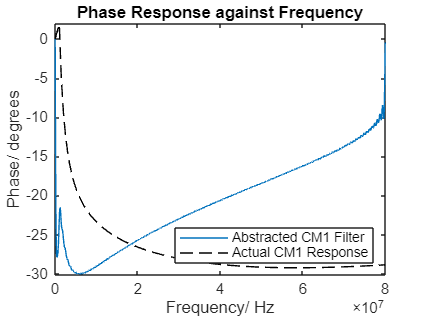


% Plotting Phase Response vs Normalized Frequency
figure
plot((W/pi)*(80E6), (angle(H))*(-180/pi))
hold on
plot((norm_freq)*(80E6),(angle(complex_CM4))*(180/pi),'k--')
legend('Abstracted CM1 Filter', 'Actual CM1 Response',Location = 'southeast')
title('Phase Response against Frequency')
ylabel('Phase/ degrees')
xlabel('Frequency/ Hz')

### CM5

CM5data = table2array(readtable("CM5_ChannelResponse.csv","NumHeaderLines",4)); % Obtaining data from COMSOL

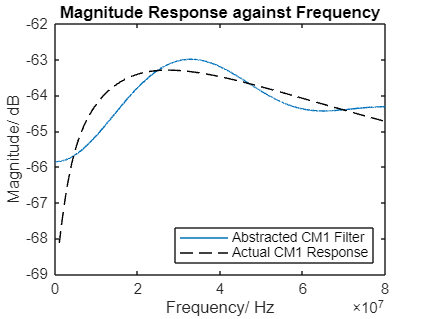

freq = [0 ; abs(CM5data(:,1))]; % Creating the frequency vector for graph plotting
norm_freq = freq/(80E6); 
complex_CM5 = [0 ; CM5data(:,2)]; 
% mag_CM1 = 20*log10(abs(complex_CM2)); %Computing magnitude response
% ang_CM1 = angle(complex_CM2);  % Computing phase response
 CM5 = fdesign.arbmag('N,F,A', 6, norm_freq', abs(complex_CM5)'); 
%CM5 = fdesign.arbmagnphase('N,F,H', 14, norm_freq', complex_CM5'); 

% CM5_filter = design(CM5, 'allfir', SystemObject = true); %Design filter using all valid methods
% 
% % Plotting Magnitude Response
% figure
% [H1, W] = freqz(CM5_filter{1});
% H2 = freqz(CM5_filter{2});
% H3 = freqz(CM5_filter{3});
% plot((W/pi)*(80E6),db(H1))
% hold on
% plot((W/pi)*(80E6),db(H2))
% plot((W/pi)*(80E6),db(H3))
% plot(freq,db(complex_CM5),'k--')
% hold off
% title('Magnitude Response against Frequency')
% ylabel('Magnitude/ dB')
% xlabel('Frequency/ Hz')
% legend('Equiripple Hd(1)', 'FIR Least-Squares Hd(2)','Frequency Sampling  Hd(3)','Nominal Response',Location = 'SouthEast')
% 
% % Plotting Phase Response
% figure
% [H1, W] = freqz(CM5_filter{1});
% H2 = freqz(CM5_filter{2});
% H3 = freqz(CM5_filter{3});
% plot((W/pi)*(80E6),angle(H1))
% hold on
% plot((W/pi)*(80E6),-angle(H2))
% plot((W/pi)*(80E6),-angle(H3))
% plot(freq,angle(complex_CM5),'k--')
% hold off
% title('Phase Response against Frequency')
% ylabel('Phase/ rad')
% xlabel('Frequency/ Hz')
% legend('Equiripple Hd(1)', 'FIR Least-Squares Hd(2)','Frequency Sampling  Hd(3)','Nominal Response',Location = 'NorthEast')
% 
% % Error Analysis: 
% 
% % Upsample the complex CM1 values to match the length of the filter values
% CM5_interp = interp1(freq, complex_CM5,(W/pi)*(80E6)); 
% freq_non_norm = (W/pi)*(80E6); 
% HBCindx = find((freq_non_norm >= 18.375E6)&(freq_non_norm <= 23.625E6));
% 
% % Magnitude
% abs_error_mag1 = mean(abs(db(CM5_interp(2:length(H1))) - db(H1(2:length(H1))))) % Equiripple Method
% abs_error_mag2 = mean(abs(db(CM5_interp(2:length(H1))) - db(H2(2:length(H1)))))% Least Square FIR
% abs_error_mag3 = mean(abs(db(CM5_interp(2:length(H1))) - db(H3(2:length(H1))))) % Frequency Sampling
% 
% % Phase
% abs_error_ph1 = mean(abs(angle(CM5_interp(2:length(H1))) - angle(H1(2:length(H1))))) % Equiripple Method
% abs_error_ph2 = mean(abs(angle(CM5_interp(2:length(H1))) - -angle(H2(2:length(H1)))))% Least Square FIR
% abs_error_ph3 = mean(abs(angle(CM5_interp(2:length(H1))) - -angle(H3(2:length(H1))))) % Frequency Sampling
% 
% % HBC Band: 
% % Magnitude
% abs_error_HBCmag1 = mean(abs(db(CM5_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H1(HBCindx(1):HBCindx(length(HBCindx)))))) % Equiripple Method
% abs_error_HBCmag2 = mean(abs(db(CM5_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H2(HBCindx(1):HBCindx(length(HBCindx)))))) % Least Square FIR
% abs_error_HBCmag3 = mean(abs(db(CM5_interp(HBCindx(1):HBCindx(length(HBCindx)))) - db(H3(HBCindx(1):HBCindx(length(HBCindx)))))) % Frequency Sampling
% 
% % Phase
% abs_error_HBCph1 = mean(abs(angle(CM5_interp(HBCindx(1):HBCindx(length(HBCindx)))) - angle(H1(HBCindx(1):HBCindx(length(HBCindx)))))) % Equiripple Method
% abs_error_HBCph2 = mean(abs(angle(CM5_interp(HBCindx(1):HBCindx(length(HBCindx)))) - -angle(H2(HBCindx(1):HBCindx(length(HBCindx)))))) % Least Square FIR
% abs_error_HBCph3 = mean(abs(angle(CM5_interp(HBCindx(1):HBCindx(length(HBCindx)))) - -angle(H3(HBCindx(1):HBCindx(length(HBCindx)))))) % Frequency Sampling
% 

% Design using the frequency sampling method. 
CM5_filter = design(CM5, 'firls', SystemObject = true); %Design filter using frequency sampling method

% Plotting Magnitude Response vs Normalized Frequency
figure
[H, W] = freqz(CM5_filter); 
plot((W/pi)*(80E6), db(H))
hold on
plot((norm_freq)*(80E6),db(complex_CM5),'k--')
legend('Abstracted CM1 Filter', 'Actual CM1 Response',Location = 'southeast')
title('Magnitude Response against Frequency')
ylabel('Magnitude/ dB')
xlabel('Frequency/ Hz')

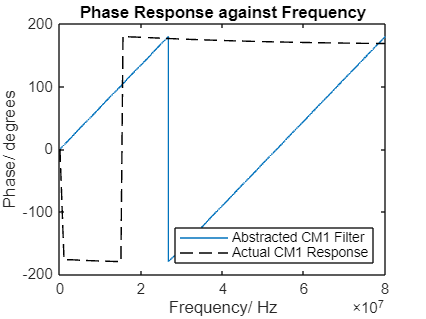


% Plotting Phase Response vs Normalized Frequency
figure
plot((W/pi)*(80E6), (angle(H))*(-180/pi))
hold on
plot((norm_freq)*(80E6),(angle(complex_CM5))*(180/pi),'k--')
legend('Abstracted CM1 Filter', 'Actual CM1 Response',Location = 'southeast')
title('Phase Response against Frequency')
ylabel('Phase/ degrees')
xlabel('Frequency/ Hz')